# Cvičení 10 - B2M31AEDA

## Nahrání dat

**Popis dat:** Pracovní data jsou uložena v souboru data.csv, který je k dispozici ke stažení na Moodle stránce tohoto předmětu, ve složce příslušného cvičení. Pro načtení dat do Matlabu využijte funkce `readtable`*.*

close all; clear; clc; addpath(genpath(fullfile([pwd '\Uni' '\grad' '\AEDA' '\week10' '\sem'])))
s = settings;
s.matlab.appearance.figure.GraphicsTheme.TemporaryValue = "light";
T = readtable('data.csv', 'ReadVariableNames', true);

## 0. Vizualizace

Vizualizaci dat jsme provedli za vás:

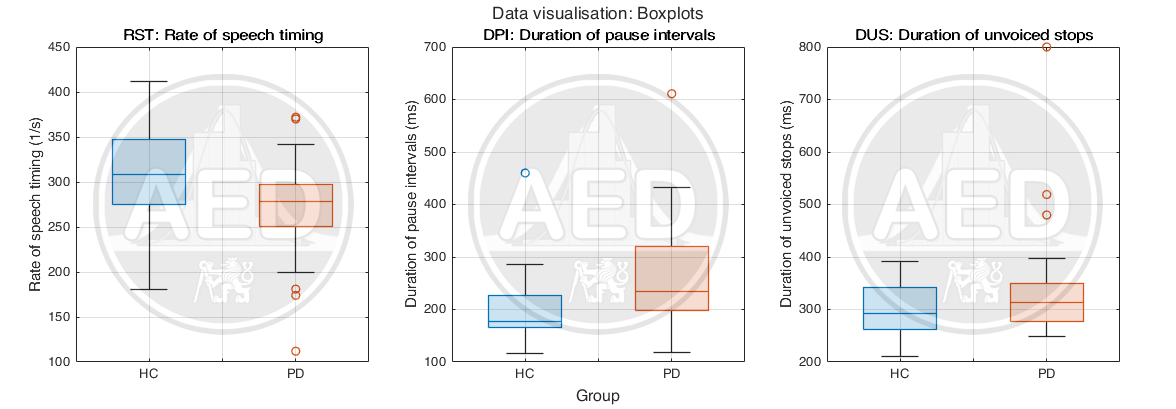

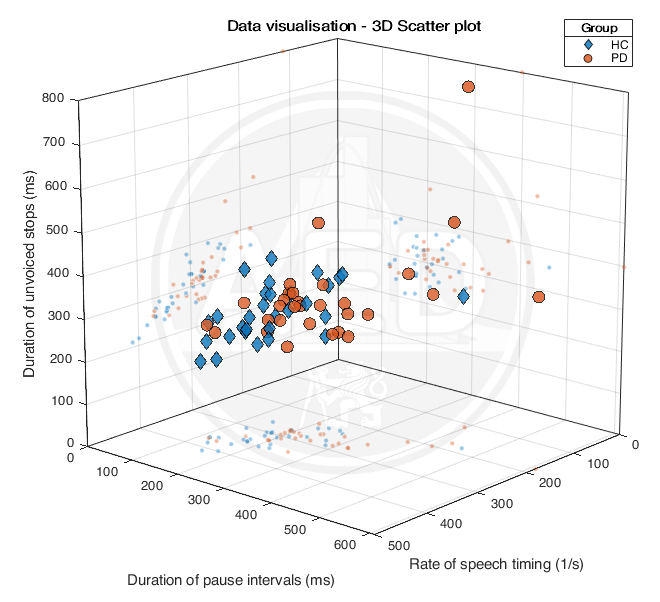

Popis jednotlivých parametrů (RST, DPI a DUS) naleznete v zadání.

## 1. Natrénování 2 modelů SVM

Z poskytnutých dat natrénujte dva klasifikační modely na standardizovaných datech (u obou modelů ponechte defaultní nastavení Matlabu pro funkci `fitcsvm`):

- SVM klasifikátor s **Lineárním Kernelem**

- SVM klasifikátor s *Radial Basis Function* **(RBF) Kernelem**

### **Otázky:**

- **Validujte kvalitu klasifikace pomocí Confusion Matrix a vyobrazte pomocí Confusion Chart.**

- **Vykreslete ROC křivky pro oba modely do JEDNOHO obrázku.**

- **Zapište hodnoty AUC pro oba modely a slovně zhodnoťte výsledky validace.**

data = [T.RST, T.DPI, T.DUS];
label = ismember(T.group, 'PD');

SVMmodel_linear = fitcsvm(data, label, 'Standardize', true, 'KernelFunction', 'linear');
[label_linear, score_linear] = predict(SVMmodel_linear, data);
[X_linear, Y_linear, ~, AUC_linear] = perfcurve(label, score_linear(:,2), 1);

SVMmodel_RBF = fitcsvm(data, label, 'Standardize', true, 'KernelFunction', 'RBF');
[label_RBF, score_RBF] = predict(SVMmodel_RBF, data);
[X_RBF, Y_RBF, ~, AUC_RBF] = perfcurve(label, score_RBF(:,2), 1);

CM_linear = confusionmat(label, label_linear);
CM_RBF = confusionmat(label, label_RBF);

### **Odpovědi:**

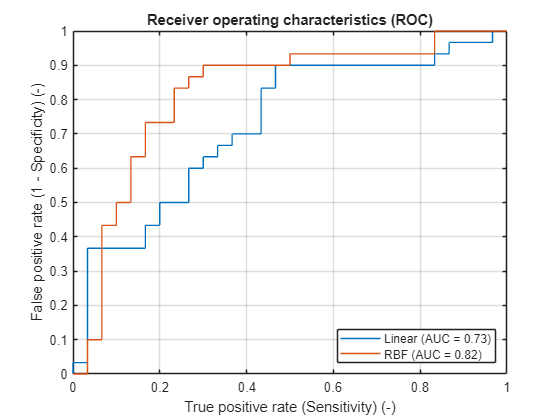

figure(1)
plot(X_linear, Y_linear, X_RBF, Y_RBF);
grid on
xlabel('True positive rate (Sensitivity) (-)');
ylabel('False positive rate (1 - Specificity) (-)');
legend(sprintf("Linear (AUC = %.2f)", AUC_linear), sprintf("RBF (AUC = %.2f)", AUC_RBF), 'Location', 'Southeast');
title('Receiver operating characteristics (ROC)');

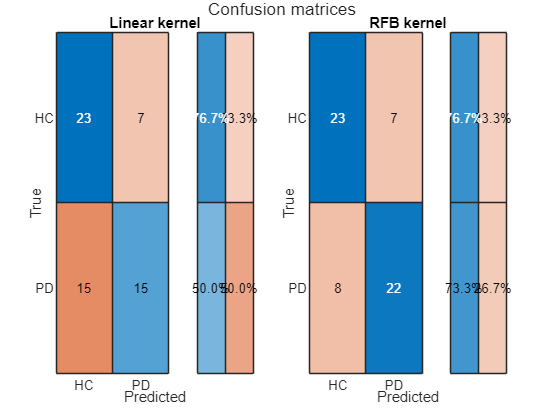

figure(2)
tiledlayout(1,2)
nexttile
confusionchart(CM_linear, {'HC', 'PD'}, 'RowSummary', 'row-normalized');
xlabel('Predicted');
ylabel('True');
title('Linear kernel');

nexttile
confusionchart(CM_RBF, {'HC', 'PD'}, 'RowSummary', 'row-normalized');
xlabel('Predicted');
ylabel('True');
title('RFB kernel');

set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
sgtitle('Confusion matrices');

## 2. Validace SVM s lineárním kernelem

Cross-validujte SVM s lineárním kernelem pomocí 5-fold cross-validace, model vždy učte na standardizovaných datech.

**Cross-validaci můžete několika způsoby:**

- Naprogramovat manuálně přes cyklus a korektní výběr testových a trénovacích dat, kdy v každé iteraci postavíte model, necháte ho klasifikovat a vyhodnotíte senz., spec. a acc. Poté reportujete mean a std těchto hodnot.

- Více méně to samé, ale pro vytvoření testovacích a trénovacích skupin použijete funkci `cvpartition`, do které zadáte počet foldů vaší cross-validace.

- Použijete funkci `kFoldPredict`, která bere za argument váš SVM model, a vrací klasifikované labely pro všechny fold v jednom vektoru (protože všechna data byla použita pro testování). V cyklu přes všechny foldy (5) se pak dostanete k indexům dat, která byla použita jako testovací, výsledky porovnáte s true labely a opět vypočtete hodnoty.

CVmodel_linear = fitcsvm(data, label, ...
    'Standardize', true, ...
    'KernelFunction', 'linear', ...
    'CrossVal', 'on', ...
    'KFold', 5);
label_CV = kfoldPredict(CVmodel_linear);

### **Otázky:**

- **Určete přesnost modelu na základě hodnot pro senzitivitu, specificitu a accuracy.**

### **Odpovědi:**

CM_CV = nan(2,2,5);
[Specificity, Sensitivity, Accuracy] = deal(nan(1,5));
for i = 1:5
    CM_CV(:,:,i) = confusionmat(label((1:12)+(i-1)*12,:), label_CV((1:12)+(i-1)*12,:));
    Sensitivity(i) = 100*CM_CV(1,1,i)/(CM_CV(1,1,i)+CM_CV(2,1,i));
    Specificity(i) = 100*CM_CV(2,2,i)/(CM_CV(2,2,i)+CM_CV(1,2,i));
    Accuracy(i) = 100*sum(diag(CM_CV(:,:,i)))/sum(sum(CM_CV(:,:,i)));
end
disp(array2table( ...
    [[Sensitivity.'; mean(Sensitivity); std(Sensitivity)], ...
    [Specificity.'; mean(Specificity); std(Specificity)], ...
    [Accuracy.'; mean(Accuracy); std(Accuracy)]], ...
    "RowNames", ["1st fold", "2nd fold", "3rd fold", "4th fold", "5th fold", "Mean", "SD"], ...
    "VariableNames", ["Sensitivity", "Specificity", "Accuracy"]))

                Sensitivity    Specificity    Accuracy
                ___________    ___________    ________

    1st fold         100              0        66.667 
    2nd fold         100              0            75 
    3rd fold      71.429             80            75 
    4th fold           0            100        16.667 
    5th fold           0            100        58.333 
    Mean          54.286             56        58.333 
    SD             50.91         51.769        24.296 



## 3. Hledání optimálních hodnot hyperparametrů RBF SVM

**Najděte optimální hodnoty hyperparametrů SVM klasifikátoru s RBF kernelem - Box constraint a Kernel scale (v přednášce značené jako C a σ) pomocí techniky Grid Search.**

- Mřížku pro techniku *Grid Search* nastavte v rozsahu hodnot **0.01 až 3.01** pro oba parametry, přičemž testovací krok zvolte jako **0.1**.

- Na každém bodu mřížky hyperparametrů vypočtěte hodnoty **specificity, senzitivity a ****accuracy** cross-validovaného modelu pomocí techniky *Leave-One-Out*.

- Ať už jste v předchozím bodě realizovali cross-validaci jakkoli, zde využijte vstupního argumentu `Leaveout` funkce `fitcsvm`.

- Výpočet modelů ve všech bodech mřížky může zabrat několik minut v závislosti na rychlosti vašeho počítače. Pokud máte nainstalovaný *Parallel Computing Toolbox*, můžete pro zrychlení výpočtu využít cyklu `parfor`, který automaticky paralelizuje výpočty na všechna procesorová jádra vašeho počítače.

Pro vykreslení a konfirmaci výsledků použijte funkci plotGridSearch dostupnou ke stažení na Moodle.

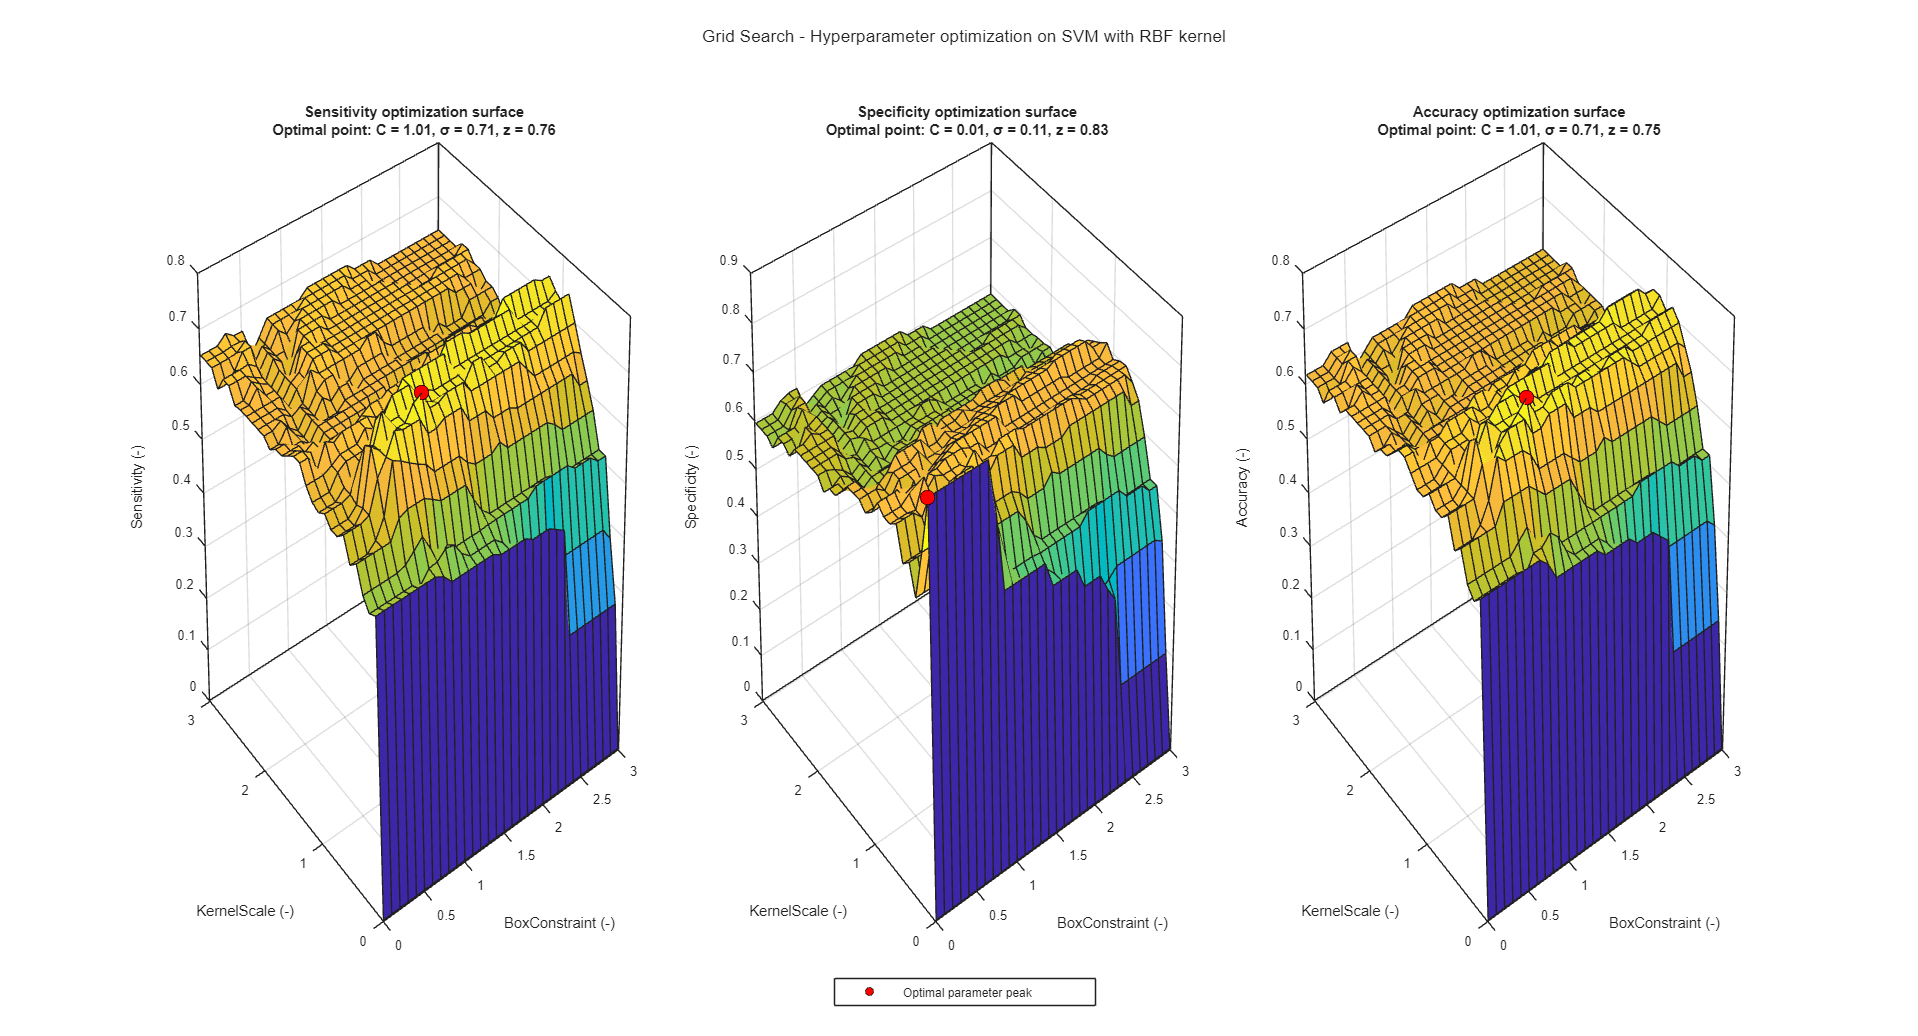

[BoxConstraint, KernelScale] = deal(0.01:0.1:3.01);
parameters = nan(length(BoxConstraint), length(BoxConstraint), 3);
for i = 1:length(BoxConstraint)
    for j = 1:length(BoxConstraint)
        CVmodel_RBF = fitcsvm(data, label, ...
            'Standardize', true, ...
            'KernelFunction', 'RBF', ...
            'BoxConstraint', BoxConstraint(i), ...
            'KernelScale', KernelScale(j), ...
            'CrossVal', 'on', ...
            'Leaveout', 'on');
        label_CV = kfoldPredict(CVmodel_RBF);
        confLT = confusionmat(label, label_CV == 1);
        parameters(i,j,1) = confLT(2,2)/(confLT(2,2)+confLT(1,2));
        parameters(i,j,2) = confLT(1,1)/(confLT(1,1)+confLT(2,1));
        parameters(i,j,3) = sum(diag(confLT))/sum(sum(confLT));
    end
end
GridSearch = plotGridSearch(BoxConstraint, KernelScale, parameters);
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

- **Odevzdejte výstup z funkce plotGridSearch a nalezené optimální hodnoty parametrů pro nejlepší hodnoty senz., spec. a acc.**

### **Odpovědi:**

fprintf("Optimal parameters C = %.3f and sigma = %.3f found using the grid-search technique yield the Sensitivity value of %.3f.", ...
    GridSearch{1,1}, GridSearch{1,2}, GridSearch{1,3});

Optimal parameters C = 1.010 and sigma = 0.710 found using the grid-search technique yield the Sensitivity value of 0.759.

fprintf("Optimal parameters C = %.3f and sigma = %.3f found using the grid-search technique yield the Specificity value of %.3f.", ...
    GridSearch{2,1}, GridSearch{2,2}, GridSearch{2,3});

Optimal parameters C = 0.010 and sigma = 0.110 found using the grid-search technique yield the Specificity value of 0.833.

fprintf("Optimal parameters C = %.3f and sigma = %.3f found using the grid-search technique yield the Accuracy value of %.3f.", ...
    GridSearch{3,1}, GridSearch{3,2}, GridSearch{3,3});

Optimal parameters C = 1.010 and sigma = 0.710 found using the grid-search technique yield the Accuracy value of 0.750.

## Nepovinný bonus:

Naprogramujte v Matlabu nejjednodušší neuronovou síť – Perceptron. Viz zadání.

% Váš kód:

